# 交差エントロピの算出

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

x, yをシンボリック変数として定義する(付録A参照)

syms x y
H=-(0.7*log2(y)+0.3*log2(1-y))

$$H = -0.4328\,\log\left(1-y\right)-1.0099\,\log\left(y\right)$$

f= diff(H,y)==0

$$f = -\frac{0.4328}{y-1}-\frac{1.0099}{y}=0$$

simplify(diff(H,y))

$$ans = -\frac{0.1443\,\left(10\,y-7\right)}{y\,\left(y-1\right)}$$

min_yVal=double(solve(f))

min_yVal = 0.7000

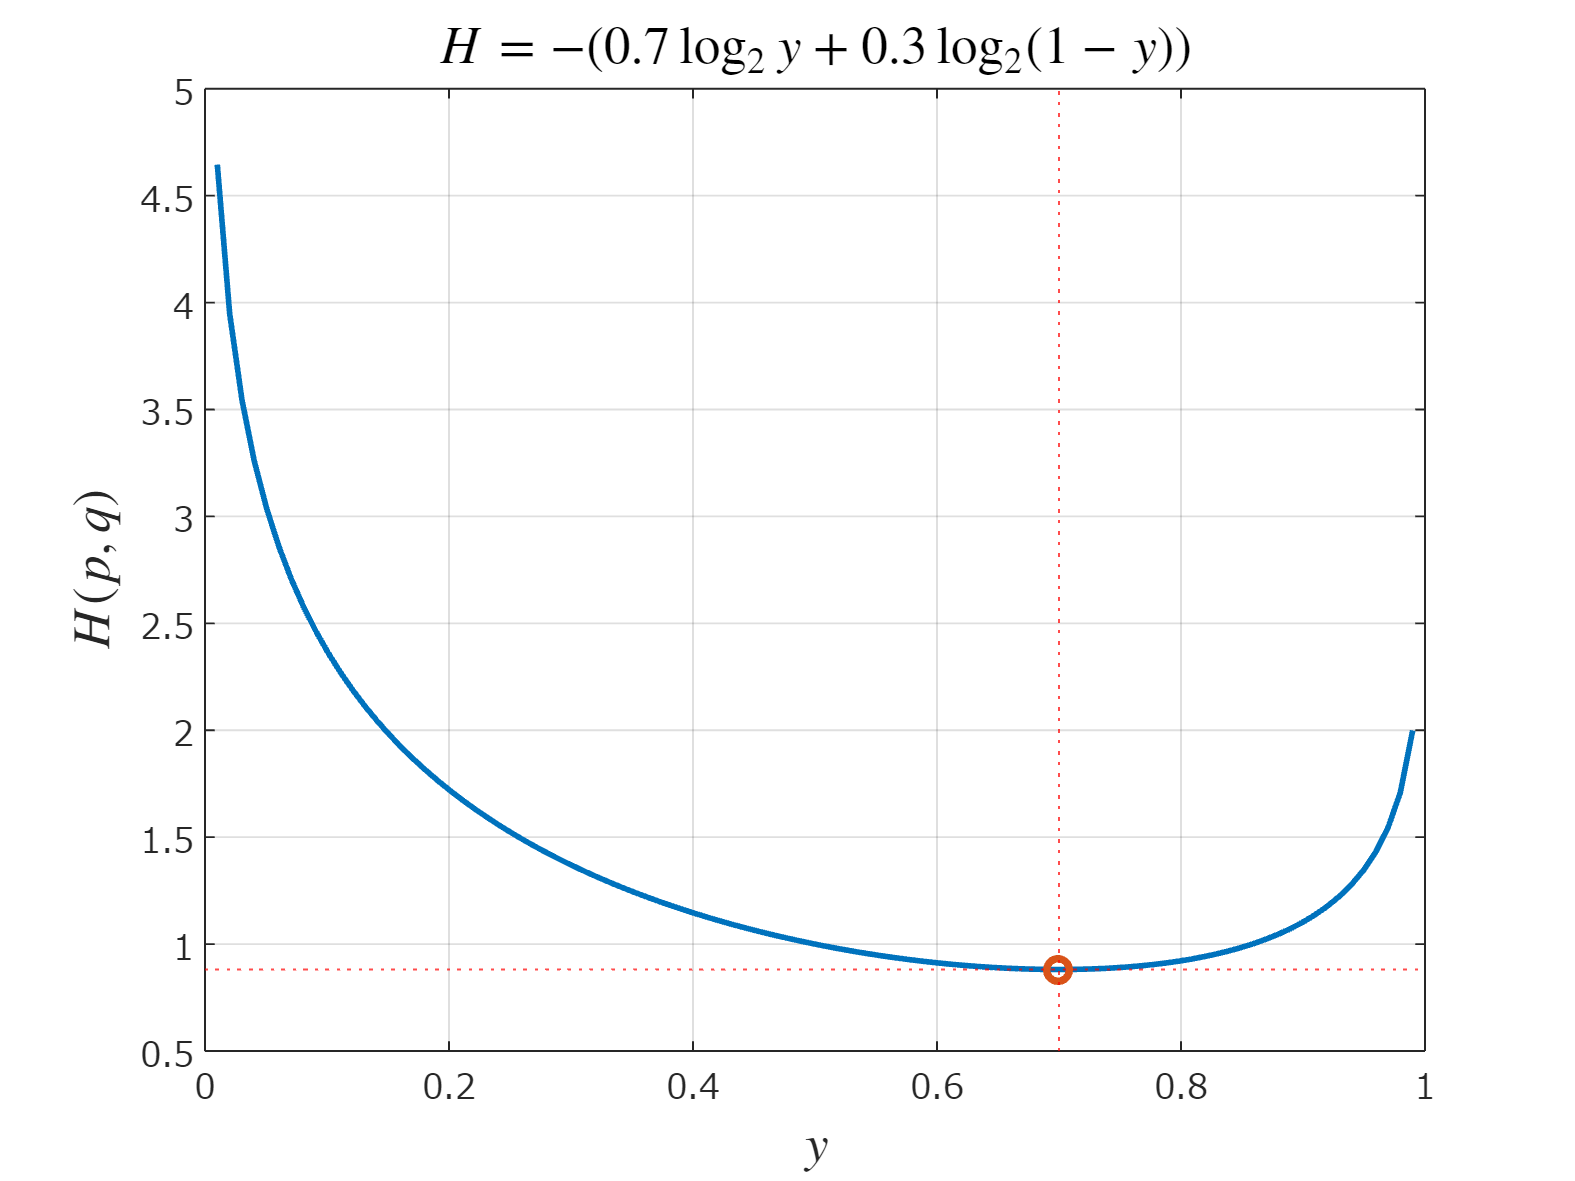


yVal=linspace(0,1,100);
HVal=subs(H,y,yVal);
figure;
plot(yVal, HVal,'linewidth',1.5);hold on;grid on;
set(gca,'fontname','メイリオ');
xlabel('$y$','Interpreter','latex','FontSize',14);
ylabel('$H(p,q)$','Interpreter','latex','FontSize',14);
hold on;
plot(min_yVal, subs(H,y,min_yVal),'o','linewidth',2);
xline(min_yVal,'r:');
yline(double(subs(H,y,min_yVal)),'r:');
title('$H=-(0.7\log_2 y +0.3\log_2 (1-y))$','Interpreter','latex','FontSize',14)
exportgraphics(gcf,'fig_CrossEntropySample.pdf');